## Plot PA103 Rd3 dataset 

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Import data from xlsx
excelFileName = 'PA103_Rd3_dataset.xlsx';
opts = detectImportOptions(excelFileName);
opts.Sheet = 'PA103_Rd3';
opts.PreserveVariableNames = true;
% Read the excel file
excelData = readtable(excelFileName,opts);
numericData = table2array(excelData(1:end,2:13));
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Extract PA103 Rd3 + phage Fern dilutions
Time = numericData(:,1); % Time 
Ctrl = numericData(:,2);
X9 = numericData(:,3);
X8 = numericData(:,4);
X7 = numericData(:,5);
X6 = numericData(:,6);
X5 = numericData(:,7);
X4 = numericData(:,8);
X3 = numericData(:,9);
X2 = numericData(:,10);
X1 = numericData(:,11);
X0 = numericData(:,12);
Low_Group = mean([Ctrl,X9,X8],2);
Medium_Group = mean([X7,X6,X5],2);
Medium_High_Group = mean([X4,X3],2);
High_Group = mean([X2,X1,X0],2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot all the data into one single graph using plotly
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
data = {
    %%%%%%%%%%%%%%%%%%%%%%%   
    struct(...
    'x', Time, ...
    'y', Ctrl, ...
    'type', 'scatter',...
    'name', 'Ctrl',...
    'line', struct('color','rgb(0,0,0)','width',3))...% black

    struct(...
    'x', Time, ...
    'y', X9, ...
    'type', 'scatter',...
    'name', 'X9',...
    'line', struct('color','rgb(0,0,0)','width',3))...% black

    struct(...
    'x', Time, ...
    'y', X8, ...
    'type', 'scatter',...
    'name', 'X8',...
    'line', struct('color','rgb(0,0,0)','width',3))...% black

    struct(...
    'x', Time, ...
    'y', X7, ...
    'type', 'scatter',...
    'name', 'X7',...
    'line', struct('color','rgb(0,0,255)','width',3))...% blue

    struct(...
    'x', Time, ...
    'y', X6, ...
    'type', 'scatter',...
    'name', 'X6',...
    'line', struct('color','rgb(0,0,255)','width',3))...% blue

    struct(...
    'x', Time, ...
    'y', X5, ...
    'type', 'scatter',...
    'name', 'X5',...
    'line', struct('color','rgb(0,0,255)','width',3))...% blue

    struct(...
    'x', Time, ...
    'y', X4, ...
    'type', 'scatter',...
    'name', 'X4',...
    'line', struct('color','rgb(0,128,0)','width',3))...% green

    struct(...
    'x', Time, ...
    'y', X3, ...
    'type', 'scatter',...
    'name', 'X3',...
    'line', struct('color','rgb(0,128,0)','width',3))...% green


    struct(...
    'x', Time, ...
    'y', X2, ...
    'type', 'scatter',...
    'name', 'X2',...
    'line', struct('color','rgb(255,0,0)','width',3))...% red

    struct(...
    'x', Time, ...
    'y', X1, ...
    'type', 'scatter',...
    'name', 'X1',...
    'line', struct('color','rgb(255,0,0)','width',3))...% red

    struct(...
    'x', Time, ...
    'y', X0, ...
    'type', 'scatter',...
    'name', 'X0',...
    'line', struct('color','rgb(255,0,0)','width',3))...% red

    struct(...
    'x', Time, ...
    'y', Low_Group, ...
    'type', 'scatter',...
    'name', 'Low (Ctrl,X9,X8)',...
    'line', struct('color','rgb(0,0,0)','width',5))...% black

    struct(...
    'x', Time, ...
    'y', Medium_Group, ...
    'type', 'scatter',...
    'name', 'Medium (X7,X6,X5)',...
    'line', struct('color','rgb(0,0,255)','width',5))...% blue

    struct(...
    'x', Time, ...
    'y', Medium_High_Group, ...
    'type', 'scatter',...
    'name', 'Medium High (X4,X3)',...
    'line', struct('color','rgb(0,128,0)','width',5))...% green

    struct(...
    'x', Time, ...
    'y', High_Group, ...
    'type', 'scatter',...
    'name', 'High (X2,X1,X0)',...
    'line', struct('color','rgb(255,0,0)','width',5))...% red

};
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
layout = struct()

layout = struct with no fields.


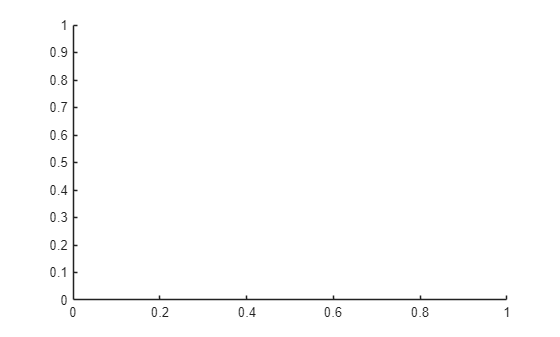

p =   plotlyfig with properties:

           data: {15×1 cell}
         layout: [1×1 struct]
         frames: {}
            url: ''
          error: []
        message: []
       UserData: [1×1 struct]
    PlotOptions: [1×1 struct]


layout.title = '<b> PA103 Rd3 Cocktail </b>';
% layout.title = 'Experimental data in Paenibacillus Larvae strain Y3650 with phage Fern';
layout.titlefont = struct('size', 45); % Set title font size and make it bold

%%%%%%%%%%%%%%%%%%%
layout.legend.font.size = 35;
layout.xaxis.title = 'Time (hours)';
layout.xaxis.titlefont.size = 40;
layout.xaxis.tickfont.size = 35;
layout.yaxis.title = 'Cell density (OD600)';
layout.yaxis.titlefont.size = 40;
layout.yaxis.tickfont.size = 35;
%%%%%%%%%%%%%%%%%%%
layout.width = 1800; % required
layout.height = 1200; % required
layout.margin.l = 170;
layout.margin.b = 120;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
p = plotlyfig; % initalize an empty figure object
p.data = data;
p.layout = layout;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
p.PlotOptions.FileName = 'PA103_Rd3_dataset'

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Create a standalone HTML file
html_file = plotlyoffline(p);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    